# Classify Objects with Pretrained Network

In this exercise, you will explore different pretrained networks and see how they classify different objects. 

## Navigate to Correct Directory

If you are in the wrong directory, you will get errors when we start working with datastores.

**Run this to check your directory.**

if isfolder('02-Images')
    disp('You are in the correct directory. Please continue.')
    addpath(genpath(pwd))
else  
    disp('Please navigate to the proper Directory')
end

You are in the correct directory. Please continue.


## Choose a Pretrained Network

net = resnet50;

## Inspect the Network

% Inspect network's layers
analyzeNetwork(net);
net.Layers

ans =   177×1 Layer array with layers:

     1   'input_1'                      Image Input                  224×224×3 images with 'zerocenter' normalization
     2   'conv1'                        2-D Convolution              64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'bn_conv1'                     Batch Normalization          Batch normalization with 64 channels
     4   'activation_1_relu'            ReLU                         ReLU
     5   'max_pooling2d_1'              2-D Max Pooling              3×3 max pooling with stride [2  2] and padding [1  1  1  1]
     6   'res2a_branch2a'               2-D Convolution              64 1×1×64 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'bn2a_branch2a'                Batch Normalization          Batch normalization with 64 channels
     8   'activation_2_relu'            ReLU                         ReLU
     


% Inspect the different classes available
% Look at the last layer in the network
classes = net.Layers(end).ClassNames

classes = 1000×1 cell array
    {'tench'                   }
    {'goldfish'                }
    {'great white shark'       }
    {'tiger shark'             }
    {'hammerhead'              }
    {'electric ray'            }
    {'stingray'                }
    {'cock'                    }
    {'hen'                     }
    {'ostrich'                 }
    {'brambling'               }
    {'goldfinch'               }
    {'house finch'             }
    {'junco'                   }
    {'indigo bunting'          }
    {'robin'                   }
    {'bulbul'                  }
    {'jay'                     }
    {'magpie'                  }
    {'chickadee'               }
    {'water ouzel'             }
    {'kite'                    }
    {'bald eagle'              }
    {'vulture'                 }
    {'great grey owl'          }
    {'European fire salamander'}
    {'common newt'             }
    {'eft'                     }
    {'spotted salamander'      }
    {'axolotl' 

## Classify the Images in the Folder

Try reading in a few of the images and display them

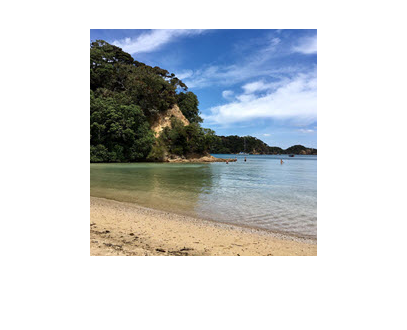

im = imread(['02-Images',filesep,'file01.jpeg']);
imshow(im)

Based on your network, you'll have to look at the first layer to determine how to resize your image. Use the following command to see input size

net.Layers(1).InputSize

ans =    224   224     3


inputSize = net.Layers(1).InputSize(1:2);

`Resize your the images and classify them.`

im = imresize(im, inputSize);
label = classify(net,im);
title(char(label))

## Run this in a Loop Using datastore

A datastore can be used when we have lots of images that we can't load into memory at once. It serves as a way to point to a collection of images when we need them without reading them directly into MATLAB at once. (See [imageDatastore documentation](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) for more details)

You can manage and read images with the datastore:

- `hasdata: `determines if data is available to read

- `read`: imports images one-by-one in consecutive order (used for loops)

- `readimage`: imports a select image

- `readall`: imports all images

Create the datastore for the entire image directory. 

imgPath = '02-Images';
ids = imageDatastore(imgPath)

ids =   ImageDatastore with properties:

                       Files: {
                              ' .../ExerciseFiles/2-PretrainedModels/02-Images/file01.jpeg';
                              ' .../ExerciseFiles/2-PretrainedModels/02-Images/file02.jpeg';
                              ' .../ExerciseFiles/2-PretrainedModels/02-Images/file03.jpeg'
                               ... and 9 more
                              }
                     Folders: {
                              ' .../deep-learning-workshop/ExerciseFiles/2-PretrainedModels/02-Images'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


Read, resize, and classify all images one at a time.

while hasdata(ids)
    
    im = read(ids);
    imR = imresize(im, inputSize);  
    [label,score] = classify(net,imR);
    maxScore = max(score);
    figure
    imshow(im)
    title([char(label) ': ' num2str(maxScore)])
   
end

ids.reset

*Copyright 2022 The MathWorks, Inc.*